# Fuel Economy - Regularized Linear Models

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

XTrain = readmatrix("./data/carEcon.xlsx", Sheet="XTrain");
XTest = readmatrix("./data/carEcon.xlsx", Sheet="XTest");
econTrain = readmatrix("./data/carEcon.xlsx", Sheet="econTrain");
econTest = readmatrix("./data/carEcon.xlsx", Sheet="econTest");

whos XTrain XTest econTrain econTest

  Name             Size            Bytes  Class     Attributes

  XTest          192x29            44544  double              
  XTrain         408x29            94656  double              
  econTest       192x1              1536  double              
  econTrain      408x1              3264  double              



## Task 1

The workspace contains the numeric predictors and response for vehicle fuel economy data. The predictors for creating a model are in `XTrain` with corresponding response in `econTrain`.

Fit ridge model

lambdaR = 0:300;
bR = ridge(econTrain, XTrain, lambdaR, 0);

## Task 2

Calculate and plot MSE. Find smallest MSE.

econPredR = bR(1, :) + XTest*bR(2:end, :);
err = econPredR - econTest;
MSER = mean(err.^2);
[minMSER, idxR] = min(MSER)

minMSER = 1.0683

idxR = 109

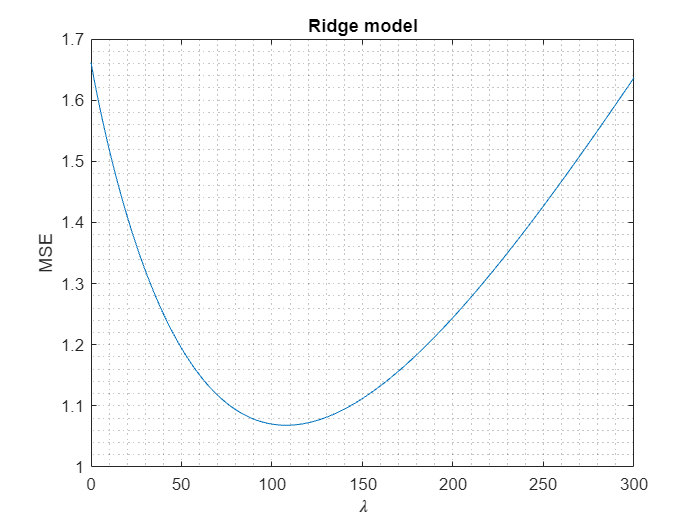


plot(lambdaR, MSER)
grid minor
xlabel("\lambda")
ylabel("MSE")
title("Ridge model")

## Task 3

Fit lasso model

lambdaL = (0:300) / length(econTrain);
[bL, fitInfo] = lasso(XTrain, econTrain, "Lambda", lambdaL);

## Task 4

Calculate and plot MSE. Find smallest MSE.

econPredL = fitInfo.Intercept + XTest*bL;
err = econPredL - econTest;
MSEL = mean(err.^2);
[minMSEL, idxL] = min(MSEL)

minMSEL = 0.9954

idxL = 77

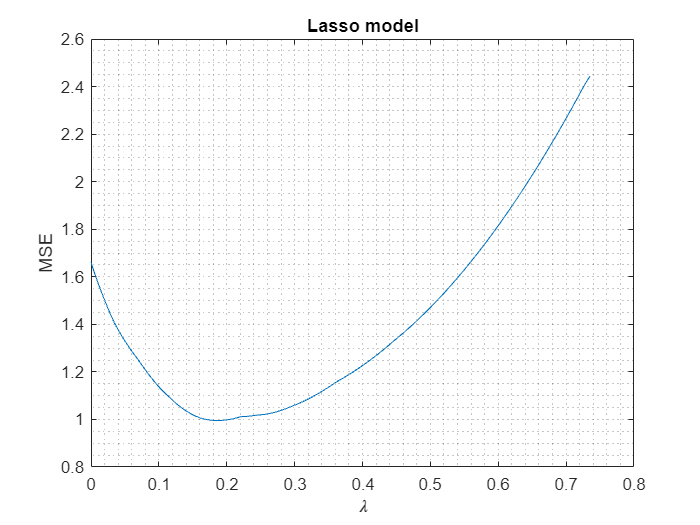


plot(lambdaL, MSEL)
grid minor
xlabel("\lambda")
ylabel("MSE")
title("Lasso model")